% clear; clc;

The 10th variable sampling finished.
The 20th variable sampling finished.
The 30th variable sampling finished.
The 40th variable sampling finished.
The 50th variable sampling finished.
The 10th subset finished.
The 20th subset finished.
The 30th subset finished.
The 40th subset finished.
The 50th subset finished.


## divide train set and test set

data = X;
label = y;

ratio = 0.7;
num_train = floor(length(label)*ratio); 
choose = randperm(length(label));

## acars

Acars = feature_acars(data(choose(1:num_train), :),...
                      label(choose(1:num_train)), 7);

The 10th variable sampling finished.
The 20th variable sampling finished.
The 30th variable sampling finished.
The 40th variable sampling finished.
The 50th variable sampling finished.
The 10th subset finished.
The 20th subset finished.
The 30th subset finished.
The 40th subset finished.
The 50th subset finished.


vsel_acars = Acars.vsel;

train_data_acars  = data(choose(1:num_train), vsel_acars);
train_label_acars = label(choose(1:num_train));
test_data_acars   = data(choose(num_train+1:end), vsel_acars);
test_label_acars  = label(choose(num_train+1:end));

## grid search

*
optimization finished, #iter = 57
nu = 0.966102
obj = -107.774047, rho = -0.856354
nSV = 114, nBSV = 114
*
optimization finished, #iter = 54
nu = 0.939130
obj = -102.750392, rho = -0.881191
nSV = 108, nBSV = 108
*
optimization finished, #iter = 53
nu = 0.929825
obj = -102.697450, rho = -0.921201
nSV = 106, nBSV = 106
*
optimization finished, #iter = 54
nu = 0.972973
obj = -99.596705, rho = -0.793423
nSV = 108, nBSV = 108
*
optimization finished, #iter = 53
nu = 0.963636
obj = -101.911063, rho = -0.892038
nSV = 106, nBSV = 106
*
optimization finished, #iter = 53
nu = 0.990654
obj = -104.870919, rho = -0.951320
nSV = 106, nBSV = 106
Total nSV = 225
*
optimization finished, #iter = 57
nu = 0.966102
obj = -107.876904, rho = -0.847566
nSV = 114, nBSV = 114
*
optimization finished, #iter = 54
nu = 0.939130
obj = -102.955081, rho = -0.879712
nSV = 108, nBSV = 108
*
optimization finished, #iter = 53
nu = 0.929825
obj = -102.932382, rho = -0.925781
nSV = 106, nBSV = 106
*
optimization finishe

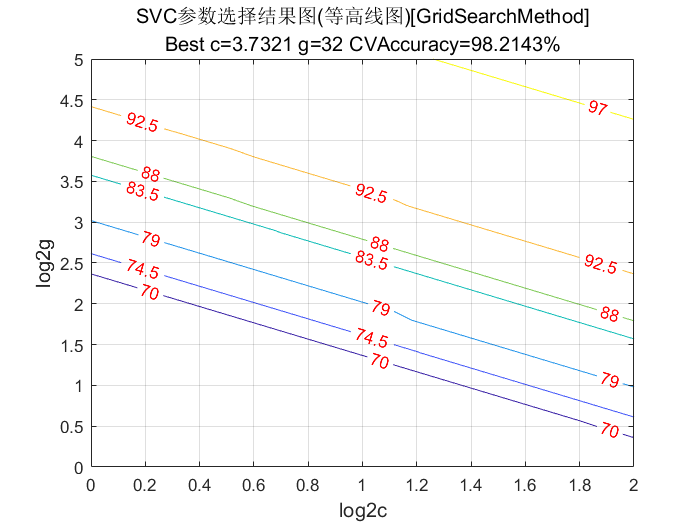

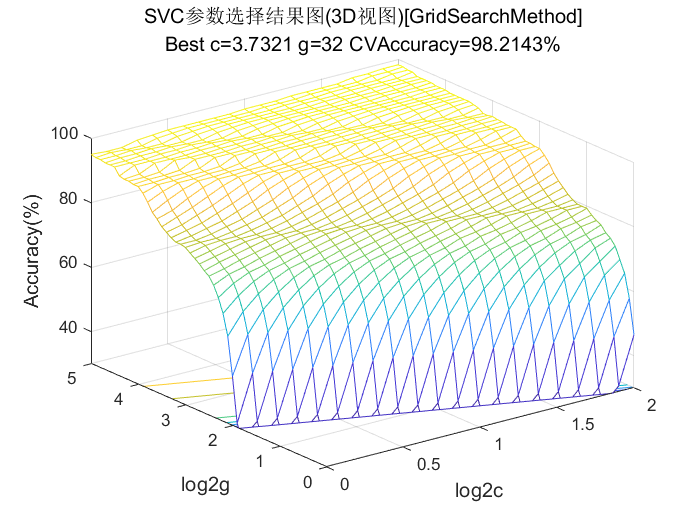

tic
[bestacc_acars,bestc_acars,bestg_acars] = ...
             svm_gridsearch(train_label_acars,train_data_acars);

toc

历时 90.052595 秒。


## train model

s = 0;
t = 2;
c = bestc_acars;
g = bestg_acars;
options_acars = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)];
model_acars = libsvmtrain(train_label_acars, train_data_acars, options_acars); 

*
optimization finished, #iter = 13
nu = 0.112897
obj = -33.165594, rho = 0.000525
nSV = 19, nBSV = 15
*
optimization finished, #iter = 40
nu = 0.139260
obj = -41.164662, rho = 0.013793
nSV = 22, nBSV = 16
*
optimization finished, #iter = 41
nu = 0.176830
obj = -51.905216, rho = -0.006932
nSV = 28, nBSV = 22
*
optimization finished, #iter = 11
nu = 0.082813
obj = -23.260876, rho = -0.015020
nSV = 13, nBSV = 10
*
optimization finished, #iter = 17
nu = 0.169887
obj = -49.312039, rho = 0.024376
nSV = 25, nBSV = 21
*
optimization finished, #iter = 48
nu = 0.581029
obj = -195.992921, rho = -0.213657
nSV = 79, nBSV = 74
Total nSV = 133


## predict test set

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label_acars, train_data_acars, model_acars);

Accuracy = 98.9286% (277/280) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label_acars, test_data_acars, model_acars);

Accuracy = 98.3333% (118/120) (classification)
